# Part 2

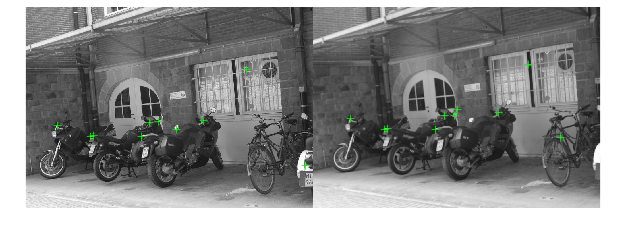

clc
clear
Image_1 = imread('Images/bikes1.ppm');
Image_1 = im2gray(Image_1);
Image_2 = imread('Images/bikes2.ppm');
Image_2 = im2gray(Image_2);

image_size = size(Image_1);

corners_img1 = detectFASTFeatures(Image_1);
corners_img1 = corners_img1.selectStrongest(10);
Square = [];

for i = 1:size(corners_img1.Location,1)
    if corners_img1.Location(i,1)-2 < 0 ||...
        corners_img1.Location(i,1)+2 > image_size(1) ||...
        corners_img1.Location(i,2)-2 < 0 ||...
        corners_img1.Location(i,2)+2 > image_size(2)
        continue
    end
    currentData = Image_1(corners_img1.Location(i,1)-2:corners_img1.Location(i,1)+2,corners_img1.Location(i,2)-2:corners_img1.Location(i,2)+2);
    Square = cat(3, Square, currentData);
end 

corners_img2 = detectFASTFeatures(Image_2);
corners_img2 = corners_img2.selectStrongest(10);
corners_img2.Location(:,1) = corners_img2.Location(:,1) + image_size(2);

combined_img = [Image_1, Image_2]; 
figure
imshow(combined_img); 
hold on;
plot(corners_img1);
plot(corners_img2);
hold off;